## **Calculo de los  parametros de la bobina**

El rango de frecuencias AM va desde **540 kHz** a **1705 kHz**

clc, clear, close all
format short g

Primero procedemos a caracterizar nuestro capacitor variable obtenido de un radio viejo.

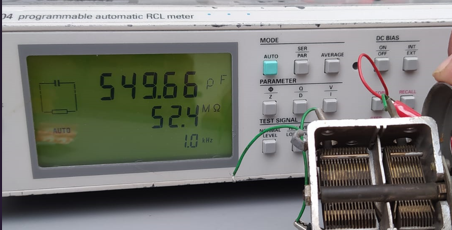

despues de realizar la misma medicion varias veces, observamos que la capacitanci maxima esta entre los 450 y 550 pF, por lo que para los calculos lo tomamos como 500pF, y como minima capacitancia el puente de impedancias nos muestra 26pF.

cmin = 26e-12; %[F] capacitancia minima
cmax = 500e-12; %[F] capacitancia maxima

Debido a la formula para la frecuencia resonante, vemos que la frecuencia maxima se da cuando la capacitancia es minima. Procedemos a calcular la frecuencia resonante en sus valores maximos y minimos debido a la variacion del capacitor

Sabemos cual es la frecuencia maxima a la que queremos llegar (**1705 kHz) **y tambien sabemos la capacitancia minima a la que llega nuestro capacitor, por lo que de la ecuacion podemos despejar L para saber la ***inductancia que necesitamos*** para resonar a dicha frecuencia:

fmax = 1700e3; %[Hz]

l = 1/(4*(pi^2)*((fmax)^2)*cmin); %[H]
Inductancia = 1/(4*(pi^2)*((fmax)^2)*cmin)*1e6 %[uH]

Inductancia =        337.11


teniendo la inductancia necesaria para resonar a la maxima frecuencia de AM, usamos este valor junto con el valor maximo de capacitancia, para encontrar el ***minimo de frecuencia*** a la que pueden resonar:

fmin = 1/(2*pi*sqrt(l*cmax)); %[Hz]
frec_min = (1/(2*pi*sqrt(l*cmax)))*1e-3 %[kHz]

frec_min =        387.66


verficamos la ***frecuencia maxima***:

fmax = 1/(2*pi*sqrt(l*cmin)); %[Hz]
frec_max = (1/(2*pi*sqrt(l*cmin)))*1e-3 %[kHz]

frec_max =          1700


Observamos que los maximos y minimos de frecuencia de resonancia calculados, se encuentran en el rango de frecuencias AM. 

Ahora que tenemos el valor de inductancia necesario, procedemos a diseñar una bobina conu buen factor de calidad.

**Diseño de una bobina de buena calidad (con alto factor Q)**

El factor de calidad o selectividad, mide la relacion entre la energia reactiva que se almacena y la energia que se disipa, durante el ciclo completo de la señal. 

Teniendo un alto valor Q, lo que busamos es que la bobina tenga una buena capacidad de almacenamiento de energia, es decir la reactancia, y reducir al minimo su resistencia real, para tener la menor perdida de energia posible.

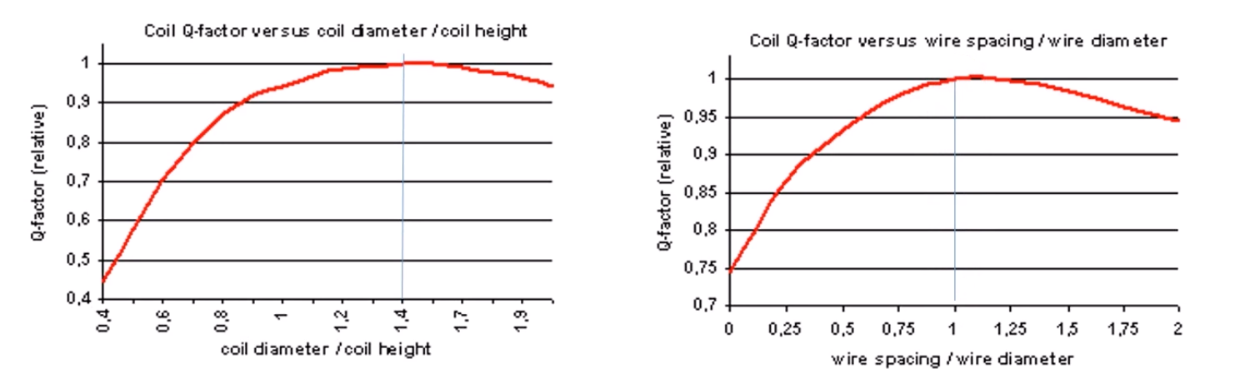

Este factor de calidad depende de la geometria de la bobina, como podemos ver en las anteriores graficas. Teniendo en cuenta estas relaciones, calculamos una bobina de tal manera que nos ofrezca un buen factor de calidad, lo mayor posible.

ya con el rango establecido procedemos a calcular los ***parametros para fabricar la bobina*** que necesitamos

d = 0.05; %[m] diametro de la bobina
long = 0.027; %[m] longitud de la bobina
A = pi*(d^2)/4; %[m^2] area transversal de la bobina
u0 = 4*pi*1e-7; %permeabilidad magnetica del aire

N = sqrt((l*long)/(u0*A)) %numero de vueltas del solenoide

N =        60.736


Ahora comparamos los calculos con lo calculado por el software coil32, para el diseño de bobinas y obtenemos lo siguiente:

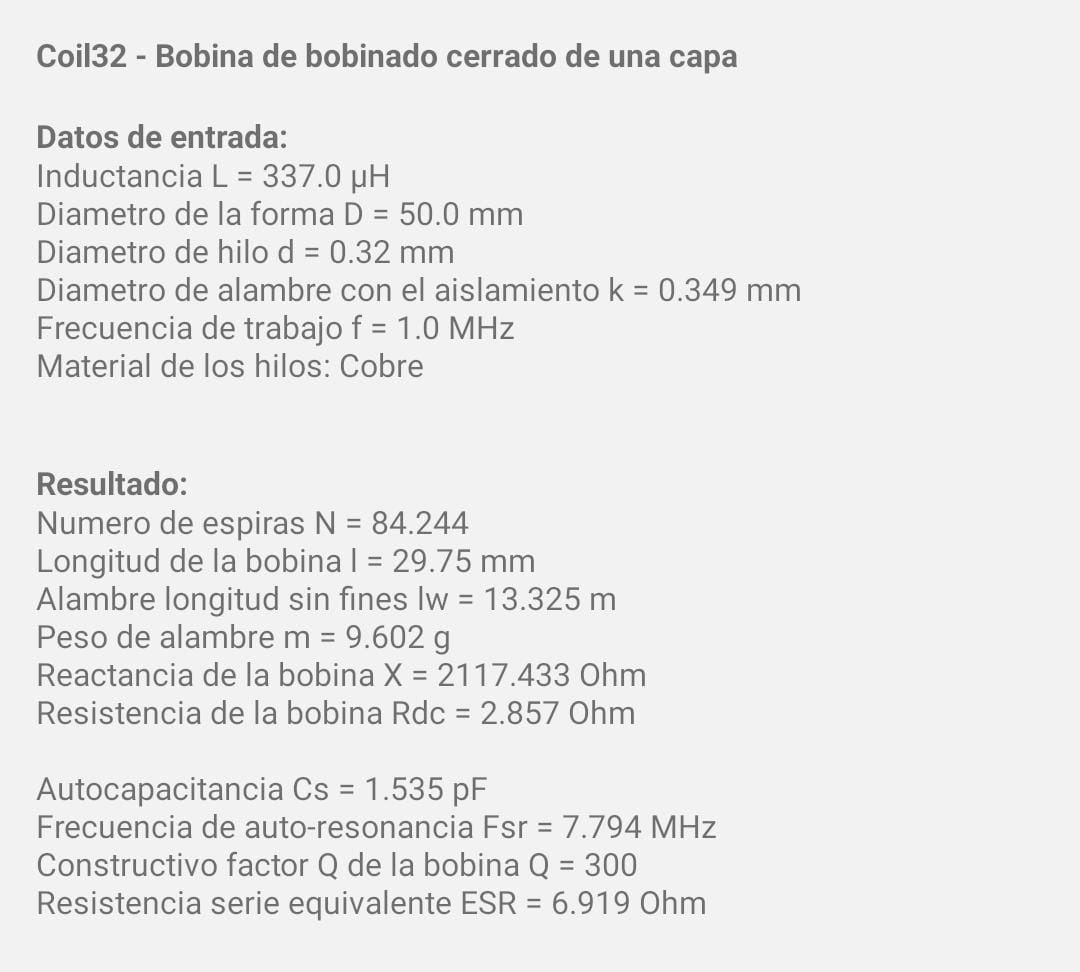

Vemos que nos da un numero de vueltas más de lo que calculamos. Esto es debido a que el software toma en cuenta variables adicionales comolos parametros del calibre del cable y ajusta el diametro y la longitud de la bobina para tener el factor Q lo mayor posible, que como se indica en los resultaos, nos arroja un Q de 300 o cual es bastante satisfactorio para este tipo de bobina. Procedemos a medir la bobina fabricada bajo estos parametros, y realizada la medicion de inductancia con el puente de impedancias, comparamos con lo calculado. 

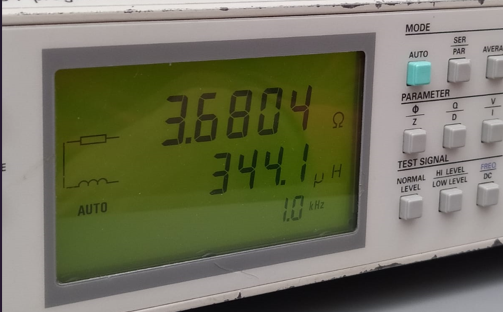

Vemos que nos dio un valor de inductancia cercano al que necesitamos, esta variacion puede ser debido a que nos pasamos de la longitud que nos indicó el software. 

## **Analisis del filtro pasabanda: Ancho de banda, factor de calidad, etc**

Ya con los parametros de la bobina, nos piden sintonizar la emisora AM '*Melodia*' **730 kHz**, hallamos la ***capacitancia necesaria*** para sintonizar esta emisora:

l = 344e-6; %[H] inductancia medida en nustra bobina
f_melodia = 730e3; %[Hz]

c = (1/(4*(pi^2)*(f_melodia^2)*l)); %[F]
c_melodia = (1/(4*(pi^2)*(f_melodia^2)*l))*1e12 %[pF] 

c_melodia =        138.18


teniendo estos valores de capacitancia e inductancia, procedemos a calcular su ancho de banda y factor de calidad

## **Simulaciones**

**Verificación de maxima impedancia**

Sabemos que la ***maxima impedancia*** de un circuito tanque, se da en la frecuencia de resonancia, para este caso seria **730kHz, **procedemos a verificuarlo en simulación:

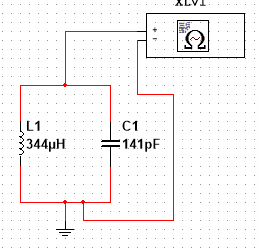

hacemos un barrido de frecuencias de 700kHz a 800kHz con el medidor de impedancias y la maxima impedancia nos deberia dar justo en la frecuencia de resonancia:

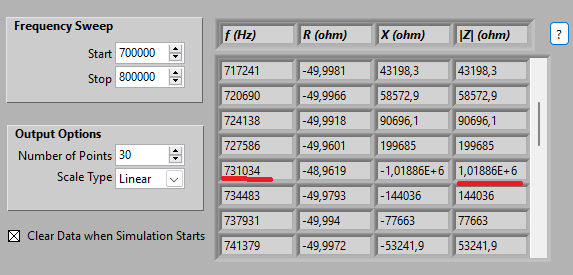

**Incorporando una señal AM**

Incorporamos una señal AM para observar el comportamiento de una ***señal con amplitud modulada***:

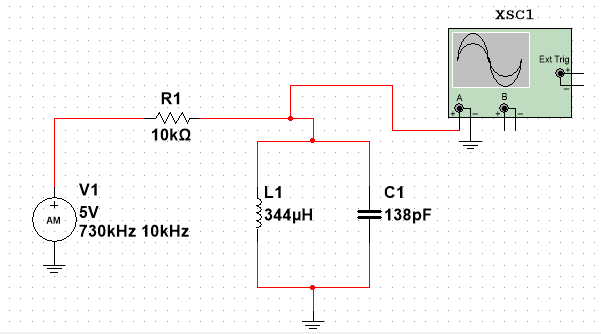

Observamos en el ***osciloscopio***:

a contionuacion lo que vemos es una señal con dos frecuencias, una señal modulada, que es donde se transmite la información, y otra señal de mas alta frecuencia que es la señal portadora:

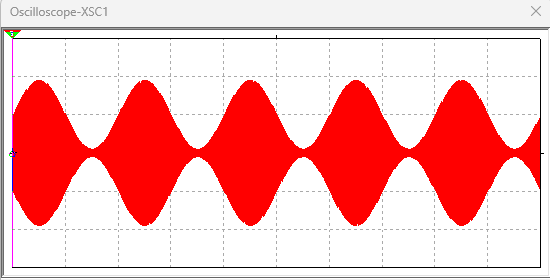

*señal modulada*

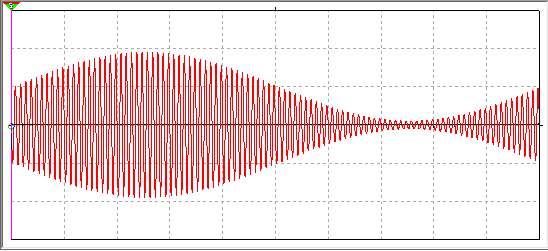

*señal portadora*

**Selectividad circuito pasabanda**

Al mismo circuito anterior le pasamos un bode plotter para ver si duagrama de bode:

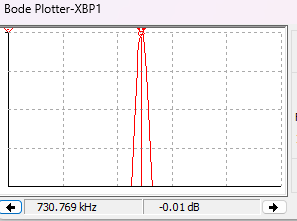

vemos que en el rango de ***frecuencias AM (500kHz - 1700kHz)*** Vemos que a la frecuencia de resonancia 730kHz, tenemos practicamente 0 dB.

Ahora verificamos el ancho de banda:

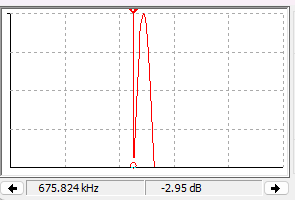

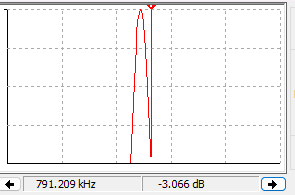

moviendo el cursor 3dB a la izquierda y ala derecha de la frecuencia de resonancia, tenemos el ancho de banda con el que podemos calcular el facor de calidad del circuito pasabanda.

Q = 730/(791-675)

Q =        6.2931


Calculado el Q nos damos cuenta que no es un circuito muy selectivo, dada la configuracion que tenemos. lo verificamos en la calculadora de ancho de banda y factor Q:

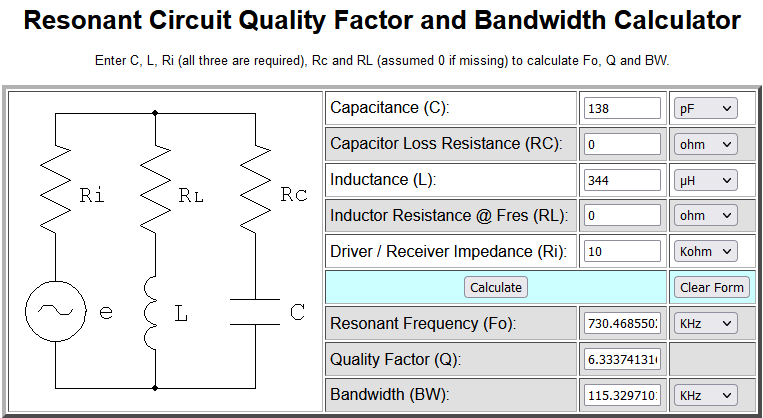

## Demodulacion de la señal AM

Se utiliza un diodo de germanio, debido que la tension que necesita para polarizarse es mucho menor que la de un diodo común, estamos hablando que el diodo de germanio genera una caida de tension de 0.25V de acuerdo con el datasheet del diodo que usamos (**Diodo Schottky de Pequeña Señal BAT 48**), mientras que un diodo común se polariza a 0.7V, en este caso es muy importante que la caida de tension sea minima puesto que el radio solo se almenta con la radiacion electromagnetica que recibe, que es muy debil, por lo que se hace necesario reducir al minimo las caidas de tension, por esto mismo la bobina se diseñó con un alto factor Q.

El diodo lo que hace es suprimir la parte negativa de la onda AM, una vez suprimida esta parte egativa, nos queda la señal de informacion (mas baja frecuencia) y la señal portadora (muy alta fecuencia), necesitamos eliminar la señal portadora, y deja pasar solo la señal de información, o sea el sonido; para eliminar la señal portadora se hace uso de un filtro pasabajos que consiste en un condensador que se encarga de atenuar los picos de muy alta frecuencia, y despeja la señal de baja frecuencia, que es el audio que vamos a escuchar en el auricular de alta impedancia.

A continuacion observamos la señal de enrada y la señal de salida con un osciloscopio:

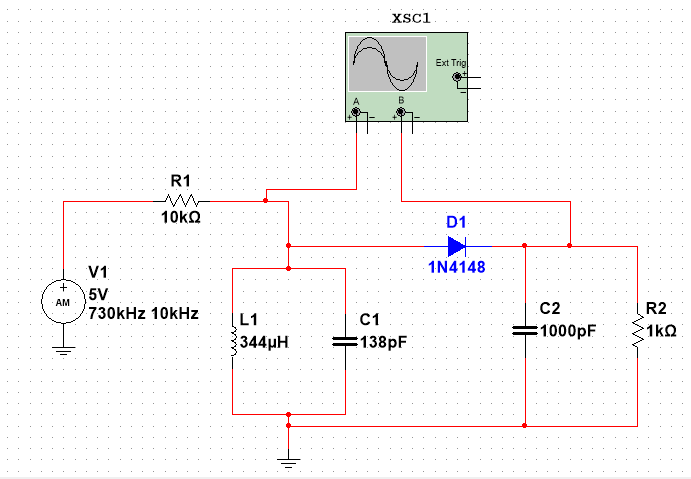

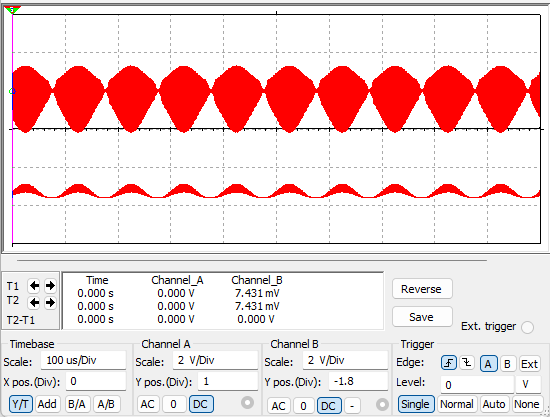

 Y como esperabamos, se observa como el filtro pasabajos hace su trabajo de atenuar la alta frecuencia de la señal, dejando pasar solo la baja, pero aun se ve la señal con rizado por lo ue conviene usar un capacitor de mayor capacidad para atenuarla aun más.